% run startup
% run("car_startup.m");

clear all
close all
clc

% Pojazd: Lancer 1.5, 955 kg
A = 2.18; % m^2
cx = 0.3;
f0 = 0.01;
eff = 0.9;
Pmax = 80; %kW
g=9.81;
m = 955; %kg
rd = 0.360; % m
brake_force=7500; %N
start_speed=10; %m/s


% opóźnienie czasu hamowania
t_opz = 1; %s

% parametry wzniesienia
angle=0;

%Parametry silnika
Mmax = 147; %Nm
n_Mmax = 4500; %rpm

% krzywa momentu
run("csv_import");
csv_data = data{:,:};
sz = size(csv_data);
csv_data(sz(1),:) = [];

torque_curve_f = polyfit(csv_data(:,1), csv_data(:,2), 2);

rpm_gear_up = 5000;
rpm_gear_down = 2500;

% Parametry skrzyni biegów
ibi = [3.31 1.91 1.31 0.97 0.81]; % przełożenia
starting_gear = 1; % bieg początkowy
ig=4.53; % przekładnia główna
gear_max=5;

% parametry startowe symulacji
car1_start_s = 0;
car2_start_s = 100;


## Krzywa momentu

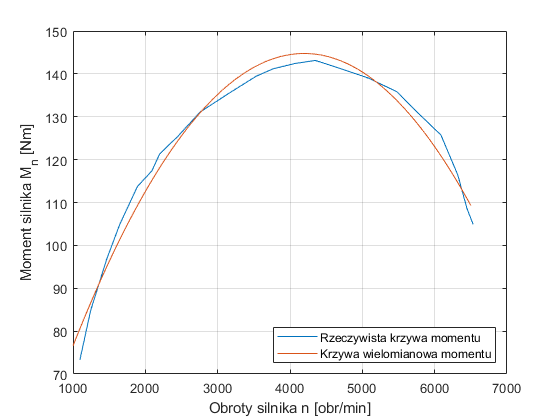

% torque curve

figure()
plot(csv_data(:,1), csv_data(:,2), 'DisplayName', "Rzeczywista krzywa momentu")
hold on

xi = 1000:6500;
plot(xi, polyval(torque_curve_f, xi), "DisplayName", "Krzywa wielomianowa momentu")
hold off

ylabel("Moment silnika M_n [Nm]")
xlabel("Obroty silnika n [obr/min]")
grid()

legend('Location', "southeast")
saveas(gcf, "./img/trq_curve.png")

% run simulation
run("car_model.slx")

## Wyniki

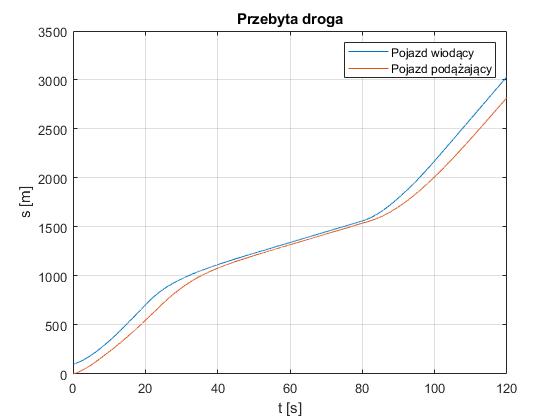


% distance driven plot plot
figure()
plot(car2.s, "DisplayName", "Pojazd wiodący")
hold on
plot(car1.s, "DisplayName", "Pojazd podążający")

ylabel("s [m]")
xlabel("t [s]")
grid()
legend()
title("Przebyta droga")

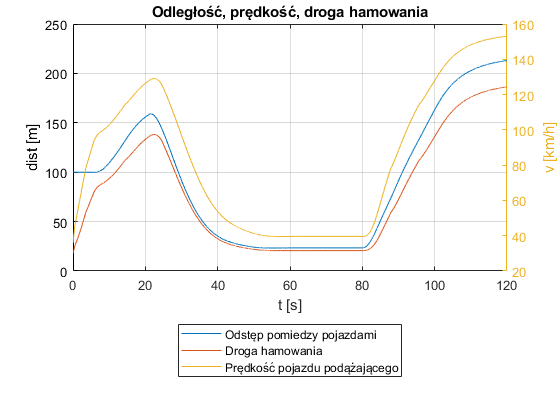


% spacing plot
figure()
plot(car1.distance_to_car2, "DisplayName", "Odstęp pomiedzy pojazdami");
hold on
plot(car1.braking_dist, "DisplayName", "Droga hamowania")
hold off

ylabel("dist [m]")

yyaxis right
plot(car1.v*3.6, "DisplayName", "Prędkość pojazdu podążającego")
ylabel("v [km/h]")


xlabel("t [s]")
grid()
legend("Location", "southoutside")
title("Odległość, prędkość, droga hamowania")

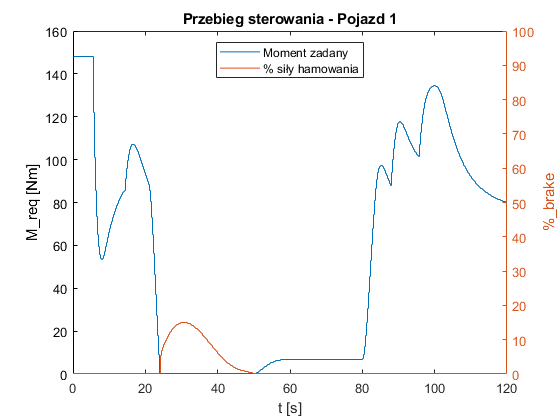


% torque & brake plot
figure()
plot(car1.set_torque, 'DisplayName', 'Moment zadany')
ylim([0 160])
ylabel("M_req [Nm]")

yyaxis right
plot(car1.set_brake, 'DisplayName', '% siły hamowania')
ylim([0 100])
title("Przebieg sterowania - Pojazd 1")


xlabel("t [s]")
ylabel("%_brake")

legend('Location',"north")


%speed plot

